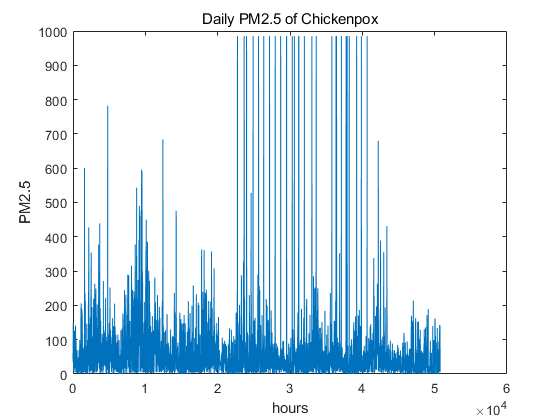

clc
clear
close all

load F:\matlab\bin\App_Desgin\beijingData.mat

data = beijingdatas;
data = data';
PM25 = flip(data);
m = numel(PM25);

for j=1:m
    if PM25(j)<0 || PM25(j)> 1500
        PM25(j)=nan;
    end
end
% PM25(30488)=nan;
PM25 = fillmissing(PM25,"linear");
% PM25 = fillmissing(PM25,"linear");
% PM25 = rmoutliers(PM25,'median');

% PM10 = data(2,:);
% PM10 = fillmissing(PM10,"linear");
% PM10 = rmoutliers(PM10,'quartiles');
% 
% AQI = data(3,:);
% AQI = fillmissing(AQI,'linear');
% AQI = rmoutliers(AQI,'quartiles');
PM = PM25;
PM = rmoutliers(PM,'quartiles');
figure
m = numel(PM25);
y = 1:m;
plot(y,PM25)
xlabel("hours")
ylabel("PM2.5")
title("Daily PM2.5 of Chickenpox")

x1 = 0;
x2 = 0;
x3 = 0;
x4 = 0;
x5 = 0;
x6 = 0;
m = numel(PM25);
for j=1:m
    if PM25(j)<=35
        PM25(j)=1; % 优
        x1 = x1+1;
    end
    if 35<PM25(j) && PM25(j)<=75 % 良
        PM25(j)=2;
        x2 = x2+1;
    end
    if 75<PM25(j) && PM25(j)<=115 % 轻度污染
        PM25(j)=3;
        x3 = x3+1;
    end
    if 115<PM25(j) && PM25(j)<=150 % 中度污染
        PM25(j)=4;
        x4 = x4+1;
    end
    if 150<PM25(j) && PM25(j)<=250 % 重度污染
        PM25(j)=5;
        x5 = x5+1;
    end
    if 250<PM25(j) && PM25(j)<=350 % 严重污染
        PM25(j)=6;
        x6 = x6+1;
    end
    if 350<PM25(j) % 严重污染
        PM25(j)=6;
        x6 = x6+1;
    end
end

m

m =        50764


x = [x1/m x2/m x3/m x4/m x5/m x6/m]

x =    0.520959735245450   0.276554251044047   0.103774328264124   0.041151209518556   0.043849972421401   0.013710503506422


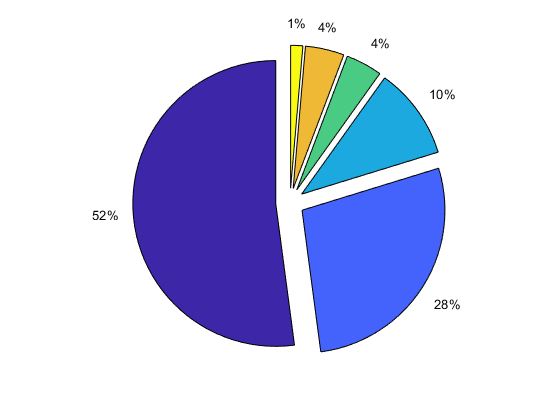

labels = {'优56%','良28%','轻度污染10%','中度污染4%','重度污染4%','严重污染1%'};
pie(x,'%.3f%%');

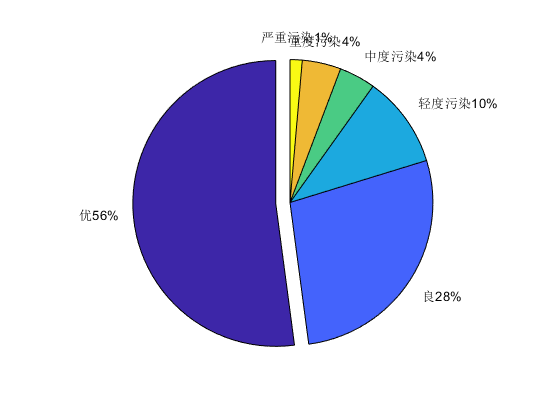

explode =  [1 0 0 0 0 0];
pie(x,explode,labels)

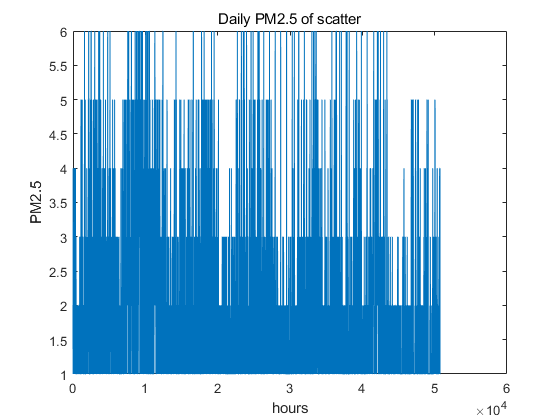


y = 1:m;
figure
plot(y,PM25)
xlabel("hours")
ylabel("PM2.5")
title("Daily PM2.5 of scatter")

% LABEL = PM25;
% index = 1;
% DATA = zeros(index,m-index+1);
% for i=1:index
%     DATA(i,:) = PM(i:end-index+i);  
% end
% DATALabel = PM25(index+1:end);
DATA = PM;

[c,l] = size(DATA);
numTimeStepsTrain = floor(0.95*l);

dataTrain = DATA(1:numTimeStepsTrain+1);
dataTrain = dataTrain;


dataTest = DATA(numTimeStepsTrain+1:end);  
dataTest = dataTest;

mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits1 = 200;
% numHiddenUnits2 = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    fullyConnectedLayer(200)
    lstmLayer(numHiddenUnits1)
%     lstmLayer(numHiddenUnits2)
    dropoutLayer(0.2)
    fullyConnectedLayer(200)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.0005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');


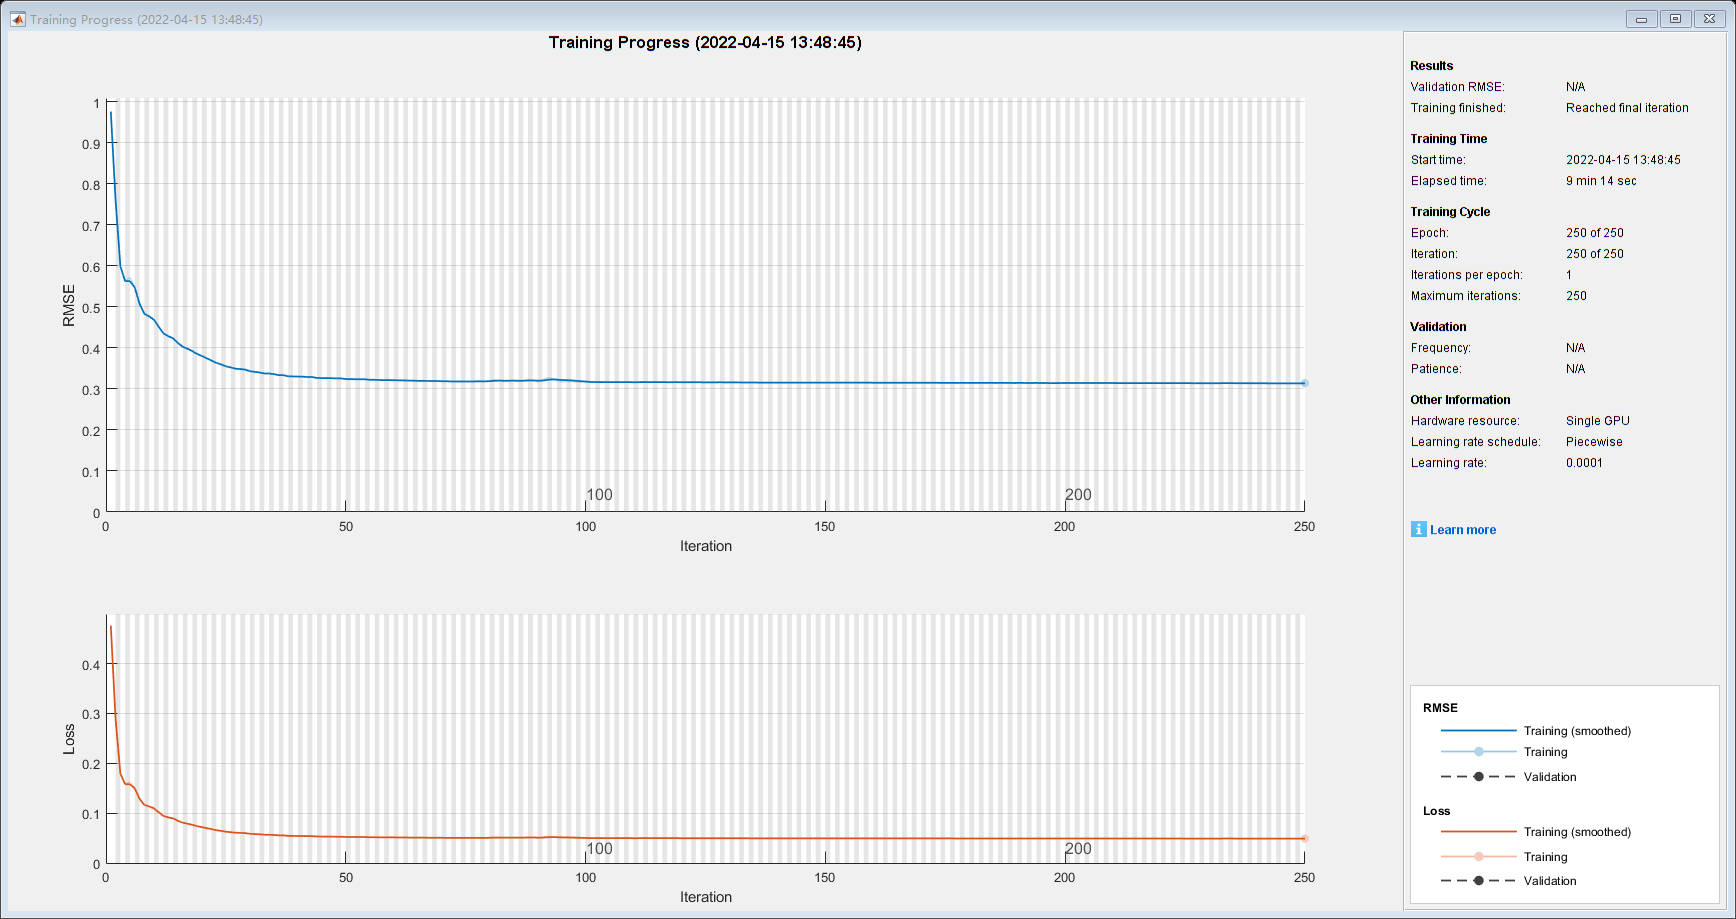

% net = trainNetwork(XTrain,YTrain,layers,options);
load ..\bin\App_Desgin\BeijingNet.mat

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
  55.9820366


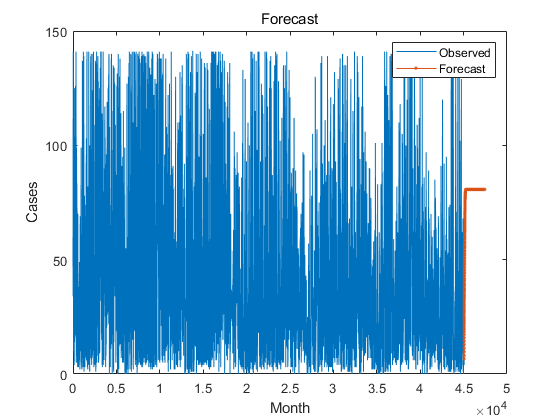

figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])

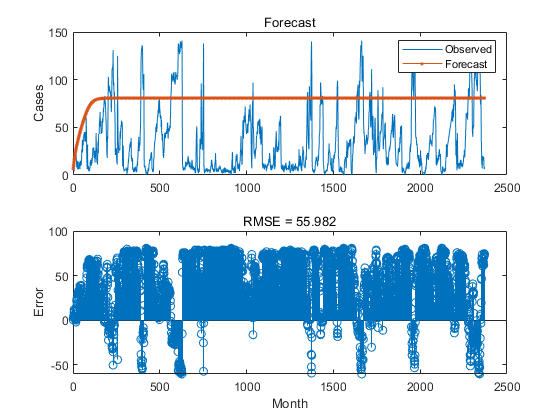

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

rmse = sqrt(mean((YPred-YTest).^2))

rmse =    7.543113068488156


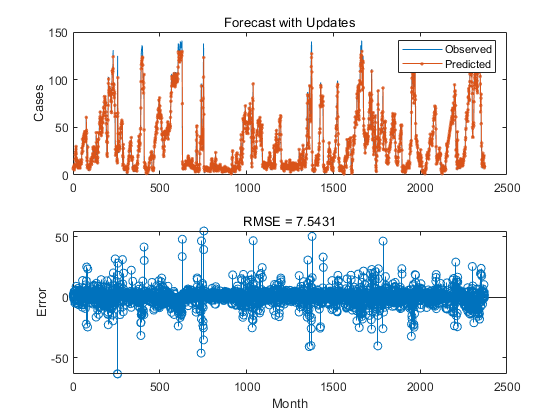

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

m = numel(YPred);
YPredLabel = YPred;
for j=1:m
    if YPredLabel(j)<=35
        YPredLabel(j)=1; % 优
    end
    if 35<YPredLabel(j) && YPredLabel(j)<=75 % 良
        YPredLabel(j)=2;
    end
    if 75<YPredLabel(j) && YPredLabel(j)<=115 % 轻度污染
        YPredLabel(j)=3;
    end
    if 115<YPredLabel(j) && YPredLabel(j)<=150 % 中度污染
        YPredLabel(j)=4;
    end
    if 150<YPredLabel(j) && YPredLabel(j)<=250 % 重度污染
        YPredLabel(j)=5;
    end
    if 250<YPredLabel(j) && YPredLabel(j)<=350 % 严重污染
        YPredLabel(j)=6;
    end
    if 350<YPredLabel(j) % 严重污染
        YPredLabel(j)=6;
    end
end

YTestLabel = YTest;
for j=1:m
    if YTestLabel(j)<=35
        YTestLabel(j)=1; % 优
    end
    if 35<YTestLabel(j) && YTestLabel(j)<=75 % 良
        YTestLabel(j)=2;
    end
    if 75<YTestLabel(j) && YTestLabel(j)<=115 % 轻度污染
        YTestLabel(j)=3;
    end
    if 115<YTestLabel(j) && YTestLabel(j)<=150 % 中度污染
        YTestLabel(j)=4;
    end
    if 150<YTestLabel(j) && YTestLabel(j)<=250 % 重度污染
        YTestLabel(j)=5;
    end
    if 250<YTestLabel(j) && YTestLabel(j)<=350 % 严重污染
        YTestLabel(j)=6;
    end
    if 350<YTestLabel(j) % 严重污染
        YTestLabel(j)=6;
    end
end
rmse = sqrt(mean((YPredLabel-YTestLabel).^2))

rmse =    0.290435180104375


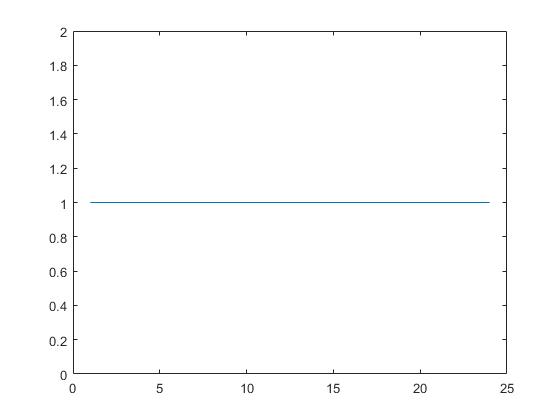

net = predictAndUpdateState(net,XTest);
[net,YPred] = predictAndUpdateState(net,XTest(end));


for i = 2:24
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

for j=1:24
    if YPred(j)<=35
        YPred(j)=1; % 优
    end
    if 35<YPred(j) && YPred(j)<=75 % 良
        YPred(j)=2;
    end
    if 75<YPred(j) && YPred(j)<=115 % 轻度污染
        YTestLabel(j)=3;
    end
    if 115<YPred(j) && YPred(j)<=150 % 中度污染
        YPred(j)=4;
    end
    if 150<YPred(j) && YPred(j)<=250 % 重度污染
        YPred(j)=5;
    end
    if 250<YPred(j) && YPred(j)<=350 % 严重污染
        YPred(j)=6;
    end
    if 350<YPred(j) % 严重污染
        YPred(j)=6;
    end
end

figure
plot(YPred)

save ../bin/App_Desgin/BeijingNet.mat net

save .\App_Desgin\Beijing24hourseP.mat YPred
save .\App_Desgin\Beijing24hourseTruth.mat YTestLabel